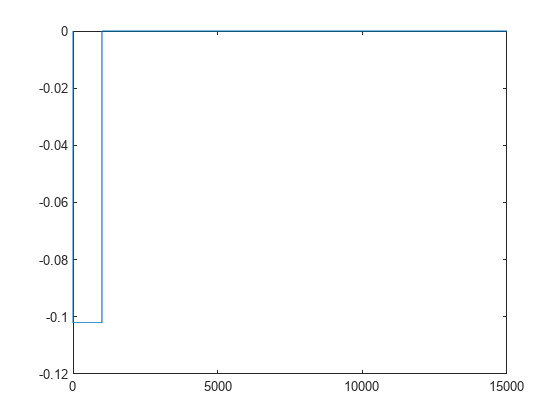

clear
R=1000;
C=9;

% Given state-space system matrices
A = -1/(R*C); % State matrix
B = [-1/C,1/R*C]; % Input matrix
C = 1; % Output matrix
D = 0; % Feedforward matrix
N=15000;
% Given input vector
u = ones(2,N); % Input vector at each time step

% Simulate the response of the system to the input
% Assume x0 is the initial state vector
t = 10000; % Define the time vector
x = zeros(size(A, 1), N); % Initialize state vector
y = zeros(size(C, 1), N); % Initialize output vector

for i = 1:1000
    % Update state vector using state-space equations
    if i == 1
        x(:, i) = 0; % Initial state vector
    else
        x(:, i) = A * x(i-1) + B * u(:,i-1);
    end
    
    % Calculate output at each time step using the mathematical operation
    y(:, i) = C * x(:, i) + D * u(i);
end

% Now, y contains the output of the system corresponding to the input u
plot(y)

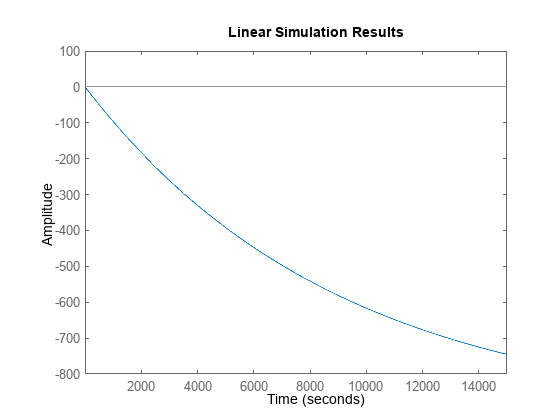

sys=(ss(A,B,C,D));
lsim(sys,u,1:N,0)